# Projeto de controle de posição

## Boas práticas


clear all;              % limpa as variáveis
clc;                    % limpa tela
close all;              % limpa as figuras


## Análise de dados de laboratório

[Velocidade,Posicao,Entrada] = ImportaDados('exp7.txt',1, 4685);

% Criando o vetor tempo
% por uma taxa de amostragem regular - T = 1e-3 = 1 ms

% linspace(X1, X2, N) generates N points between X1 and X2.
%     For N = 1, linspace returns X2.

tempo =linspace(0,length(Velocidade)*1e-3,length(Velocidade));

## Visualizar as variáveis de laboratório

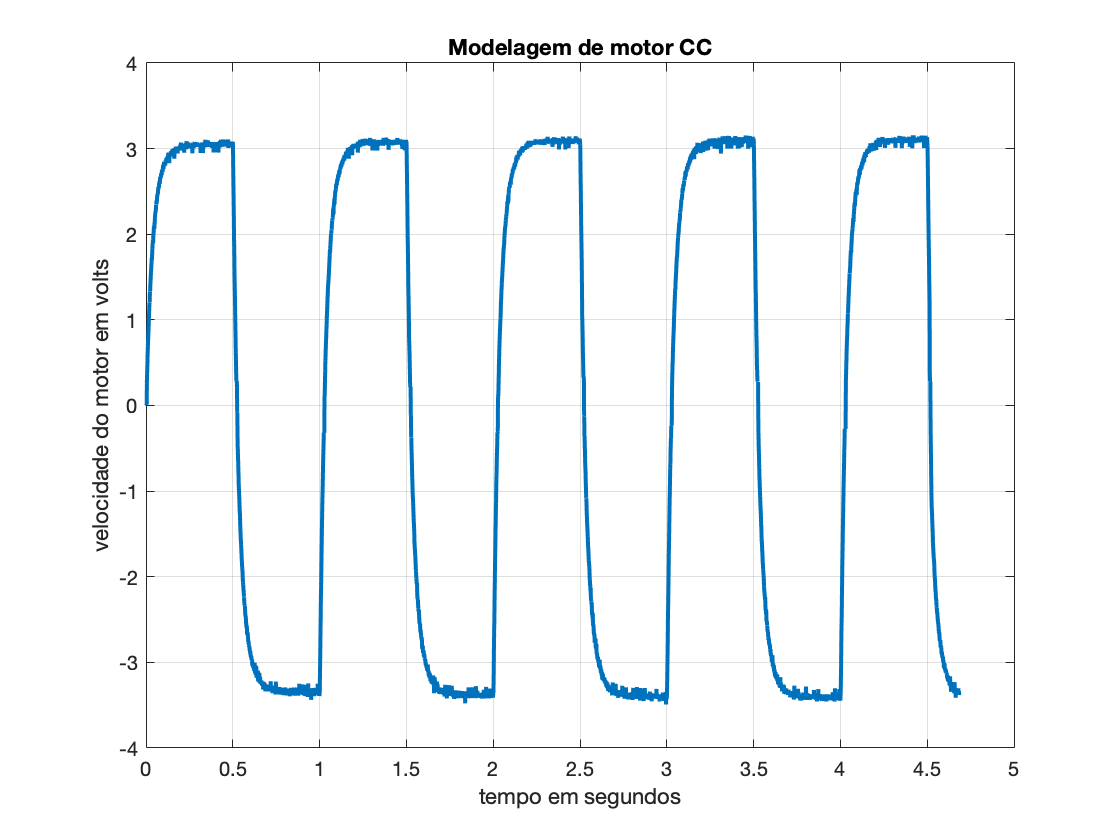

figure()
plot(tempo, Velocidade,"LineWidth",2)
xlabel('tempo em segundos');
ylabel('velocidade do motor em volts');
title('Modelagem de motor CC');
grid;

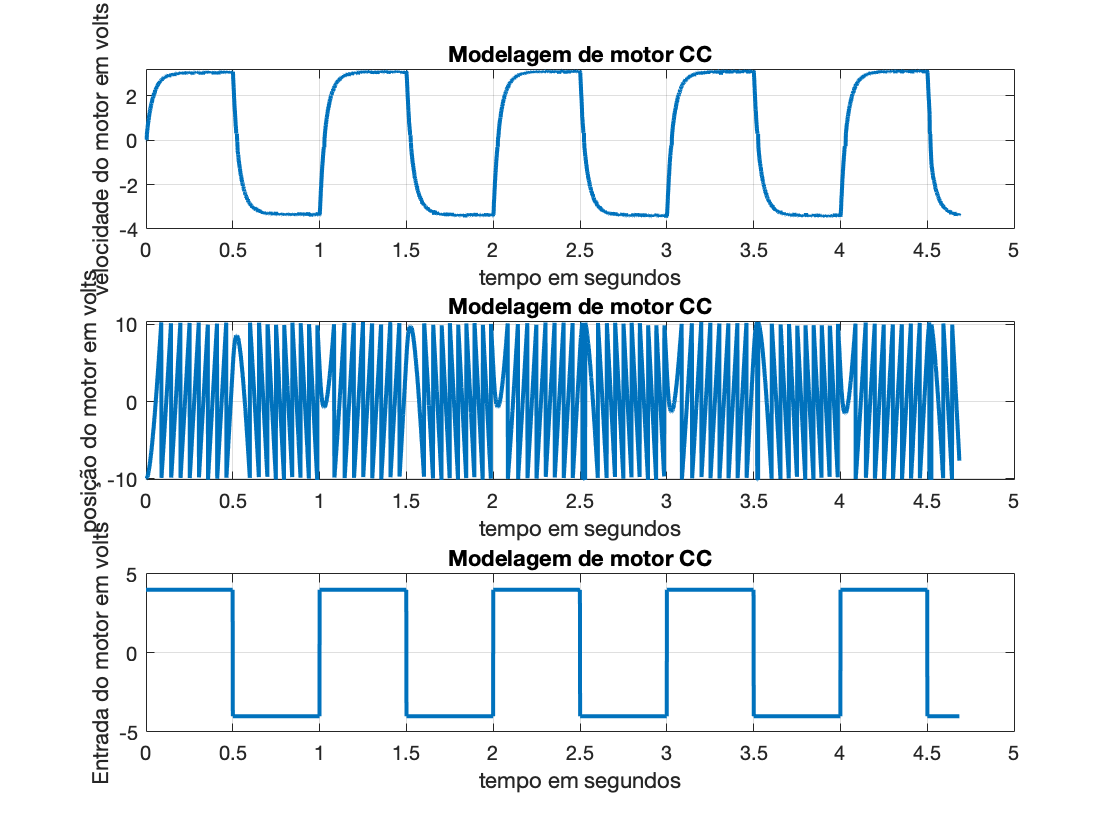


figure()

% subplot Create axes in tiled positions.
%     H = subplot(m,n,p), or subplot(mnp), breaks the Figure window
%     into an m-by-n matrix of small axes, selects the p-th axes for
%     the current plot, and returns the axes handle.  The axes are
%     counted along the top row of the Figure window, then the second
%     row, etc. 

% Gráfico 1

subplot(3,1,1);
plot(tempo, Velocidade,"LineWidth",2)
xlabel('tempo em segundos');
ylabel('velocidade do motor em volts');
title('Modelagem de motor CC');
grid;

% Gráfico 2

subplot(3,1,2);
plot(tempo, Posicao,"LineWidth",2)
xlabel('tempo em segundos');
ylabel('posição do motor em volts');
title('Modelagem de motor CC');
grid;

% Entrada 3

subplot(3,1,3);
plot(tempo, Entrada,"LineWidth",2)
xlabel('tempo em segundos');
ylabel('Entrada do motor em volts');
title('Modelagem de motor CC');
grid;

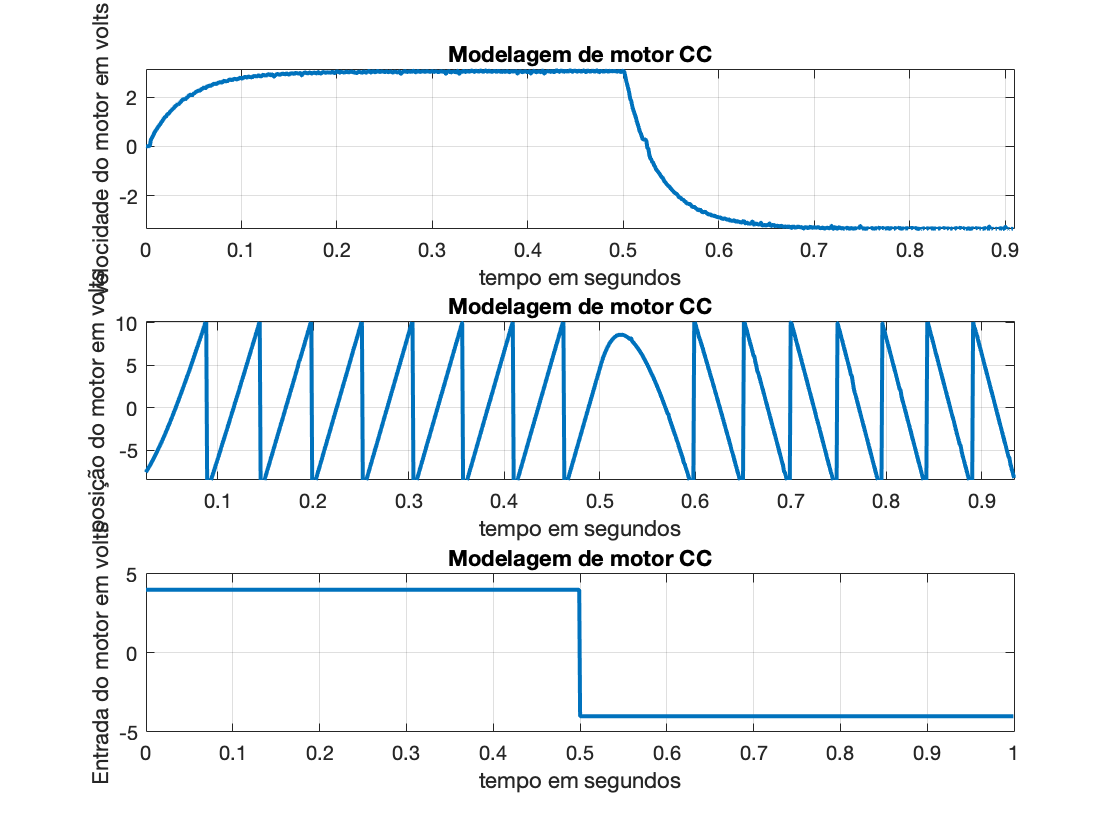


figure()

% subplot Create axes in tiled positions.
%     H = subplot(m,n,p), or subplot(mnp), breaks the Figure window
%     into an m-by-n matrix of small axes, selects the p-th axes for
%     the current plot, and returns the axes handle.  The axes are
%     counted along the top row of the Figure window, then the second
%     row, etc. 

% Gráfico 1

subplot(3,1,1);
plot(tempo(1:1000), Velocidade(1:1000),"LineWidth",2)
xlabel('tempo em segundos');
ylabel('velocidade do motor em volts');
title('Modelagem de motor CC');
grid;

% Gráfico 2

subplot(3,1,2);
plot(tempo(1:1000), Posicao(1:1000),"LineWidth",2)
xlabel('tempo em segundos');
ylabel('posição do motor em volts');
title('Modelagem de motor CC');
grid;

% Entrada 3

subplot(3,1,3);
plot(tempo(1:1000), Entrada(1:1000),"LineWidth",2)
xlabel('tempo em segundos');
ylabel('Entrada do motor em volts');
title('Modelagem de motor CC');
grid;



## Trabalhando no domínio de Laplace

N = 24;
D = [1 28];

G = tf(N,D)          % função de transferência

G =
 
    24
  ------
  s + 28
 
Continuous-time transfer function.



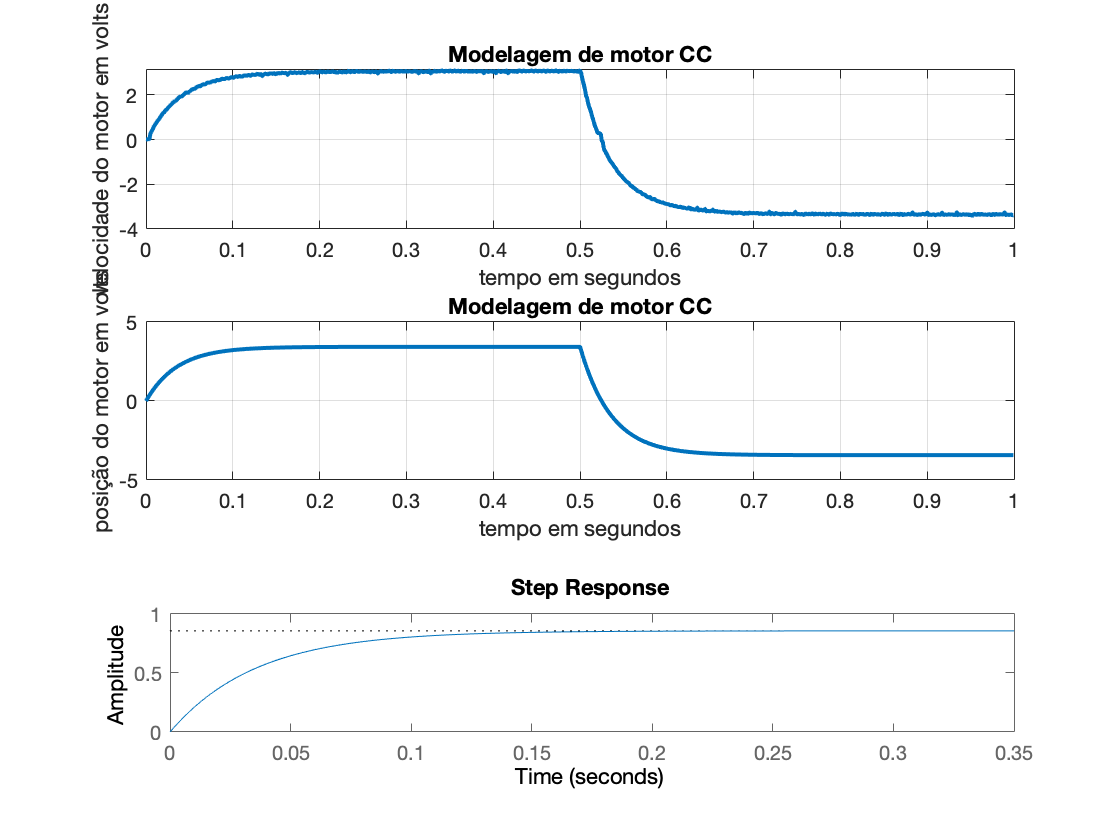


% Aplicando um degrau

step(G)

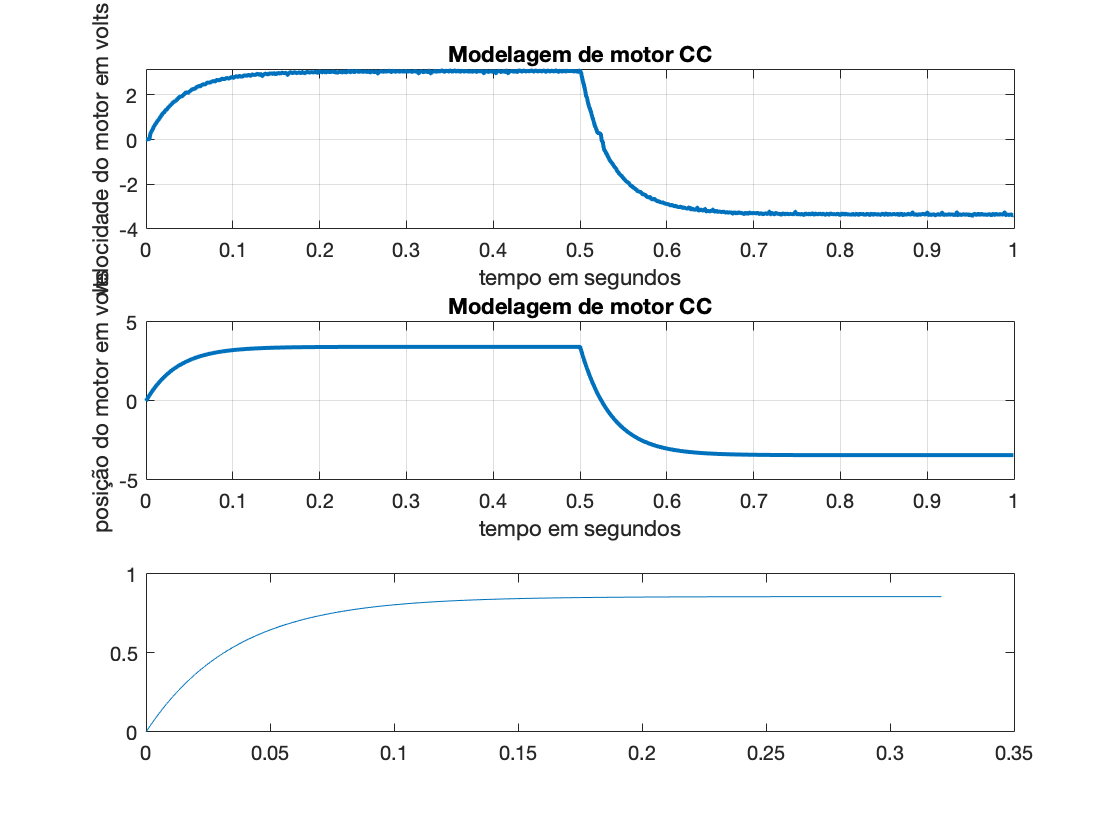

[y,t] = step(G);
plot(t,y);

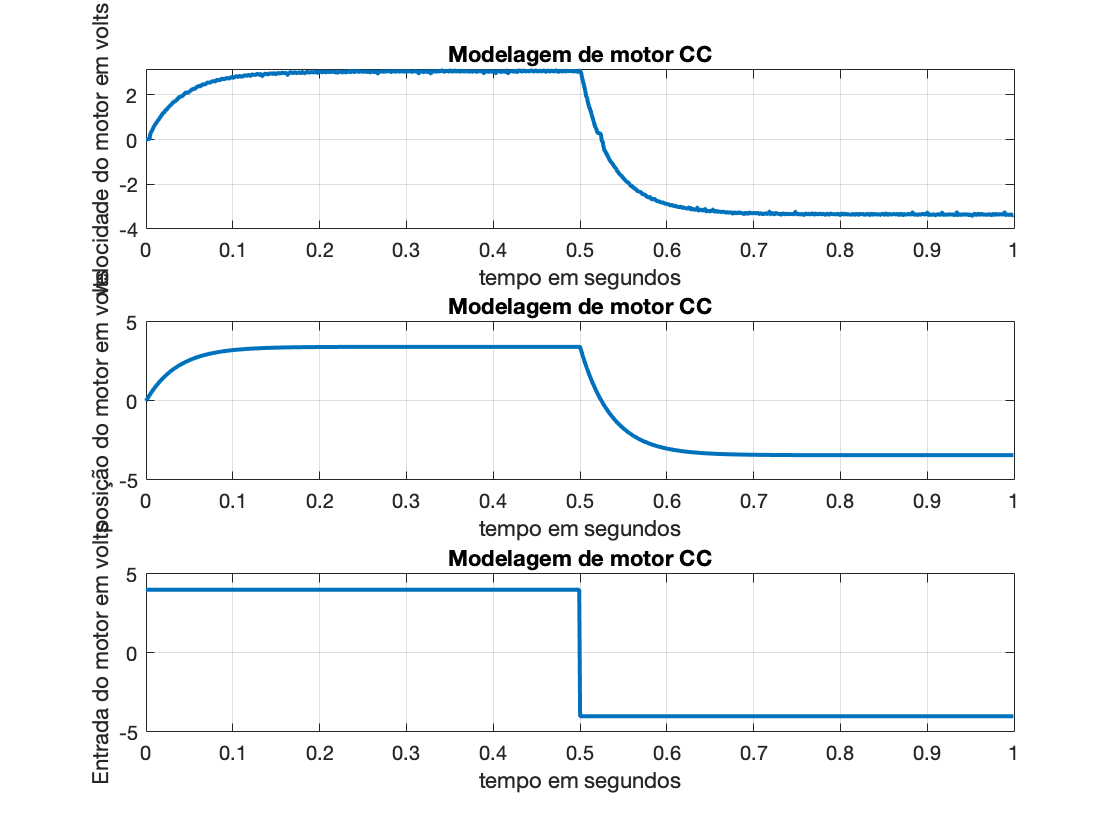

% Aplicando no modelo teórico o mesmo sinal do laboratório

yteorico = lsim(G,Entrada,tempo);


figure()

% subplot Create axes in tiled positions.
%     H = subplot(m,n,p), or subplot(mnp), breaks the Figure window
%     into an m-by-n matrix of small axes, selects the p-th axes for
%     the current plot, and returns the axes handle.  The axes are
%     counted along the top row of the Figure window, then the second
%     row, etc. 

% Gráfico 1

subplot(3,1,1);
plot(tempo(1:1000), Velocidade(1:1000),"LineWidth",2)
xlabel('tempo em segundos');
ylabel('velocidade do motor em volts');
title('Modelagem de motor CC');
grid;

% Gráfico 2

subplot(3,1,2);
plot(tempo(1:1000), yteorico(1:1000),"LineWidth",2)
xlabel('tempo em segundos');
ylabel('posição do motor em volts');
title('Modelagem de motor CC');
grid;

% Entrada 3

subplot(3,1,3);
plot(tempo(1:1000), Entrada(1:1000),"LineWidth",2)
xlabel('tempo em segundos');
ylabel('Entrada do motor em volts');
title('Modelagem de motor CC');
grid;

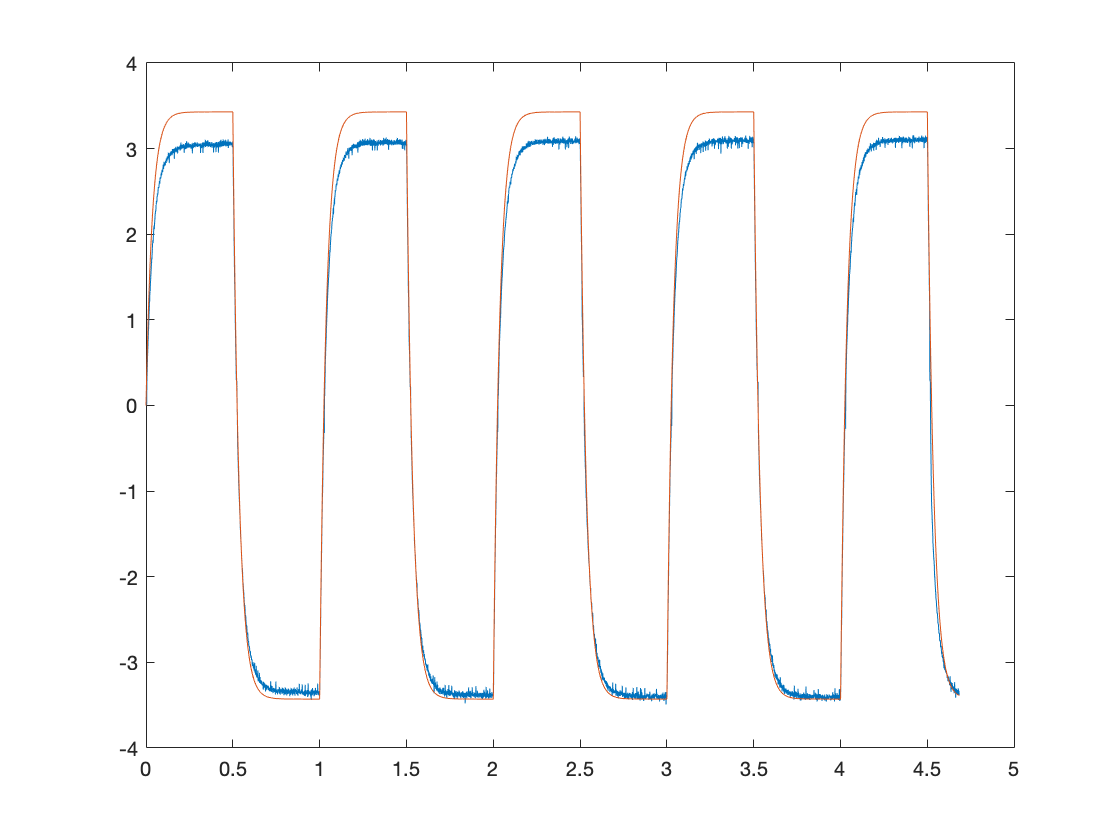

figure()

plot(tempo,Velocidade,tempo,yteorico)

## Ajustando os parâmetros do modelo 

O sinal de entrada $U(s)$ foi aplicado a um sistema cuja função de transferência gerou o sinal $\Omega(s)$. Logo a relação entre entrada e saída é dada pela função de transferência:

$\frac{\Omega(s)}{U(s)} =  \frac{K_m}{s+p_m}$ . Neste caso supomos ser de primera ordem pelo aspecto geral do sinal **Rotação**.

x0 = [1 1];    % Km = 1 e o pm = 1;

% Determinar o ponto de mínimo de [Eq] = ErroQuadratico(X,y,t,u)

X = fminsearch(@(x) ErroQuadratico(x,Velocidade,tempo,Entrada) ,x0) 

X =    22.4732   28.0882


% modelo estimado pelo Matlab

Gp = tf(X(1),[1 X(2)])

Gp =
 
    22.47
  ---------
  s + 28.09
 
Continuous-time transfer function.



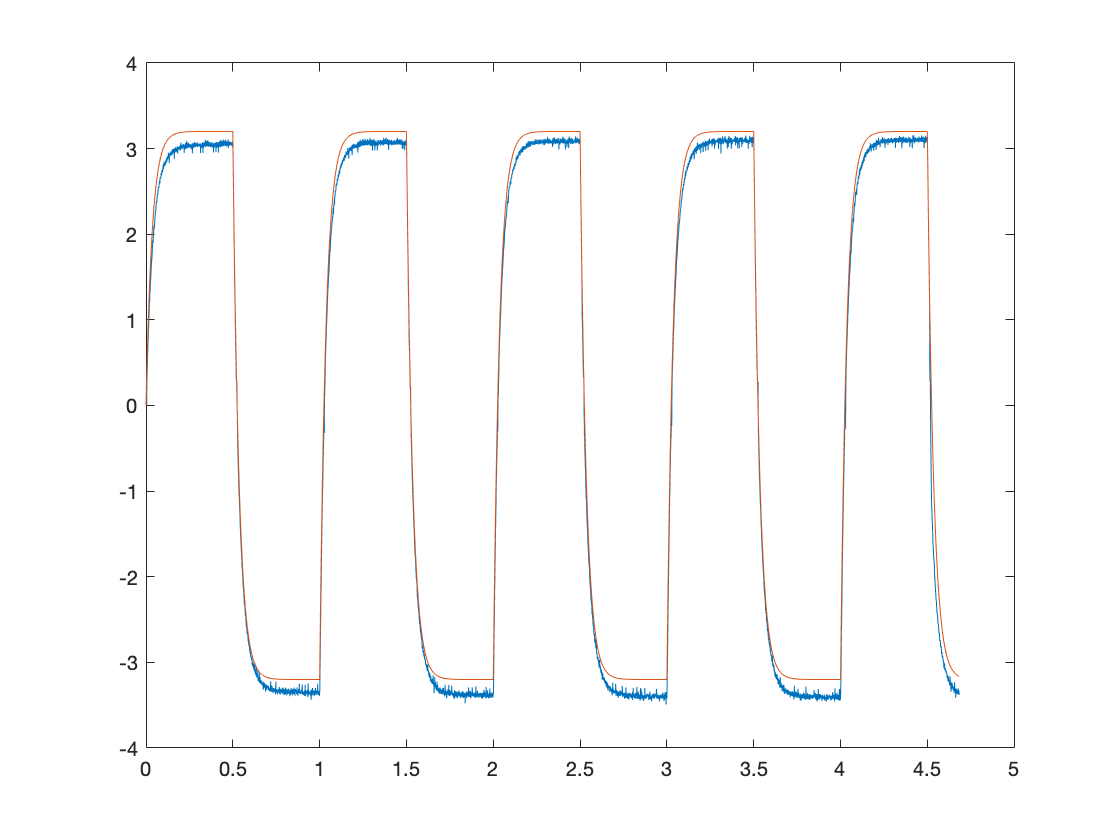

yteorico = lsim(Gp,Entrada,tempo);

figure()

plot(tempo,Velocidade,tempo,yteorico)

## Análise de polos e zeros - estabilidade

Numerador   = cell2mat(Gp.Numerator)

Numerador =          0   22.4732


Denominador = cell2mat(Gp.Denominator)

Denominador =     1.0000   28.0882



polos = roots(Denominador)

polos = -28.0882

zeros = roots(Numerador)


zeros =

  0×1 empty double column vector



isempty(polos)

ans = logical
   0


isempty(zeros)

ans = logical
   1


## Análise da Resposta temporal - erro estacionário

% escolher um tipo de controlador
% por facilidade um controlador proporcional - Kp

Kp = 1;                 % ganho do controlador
Gc = Kp;                % controlador
Gma = Gp*Gc;            % ganho de malha aberta

Gmf = feedback(Gma,1)    % ganho de malha aberta com realimentação unitária

Gmf =
 
    22.47
  ---------
  s + 50.56
 
Continuous-time transfer function.



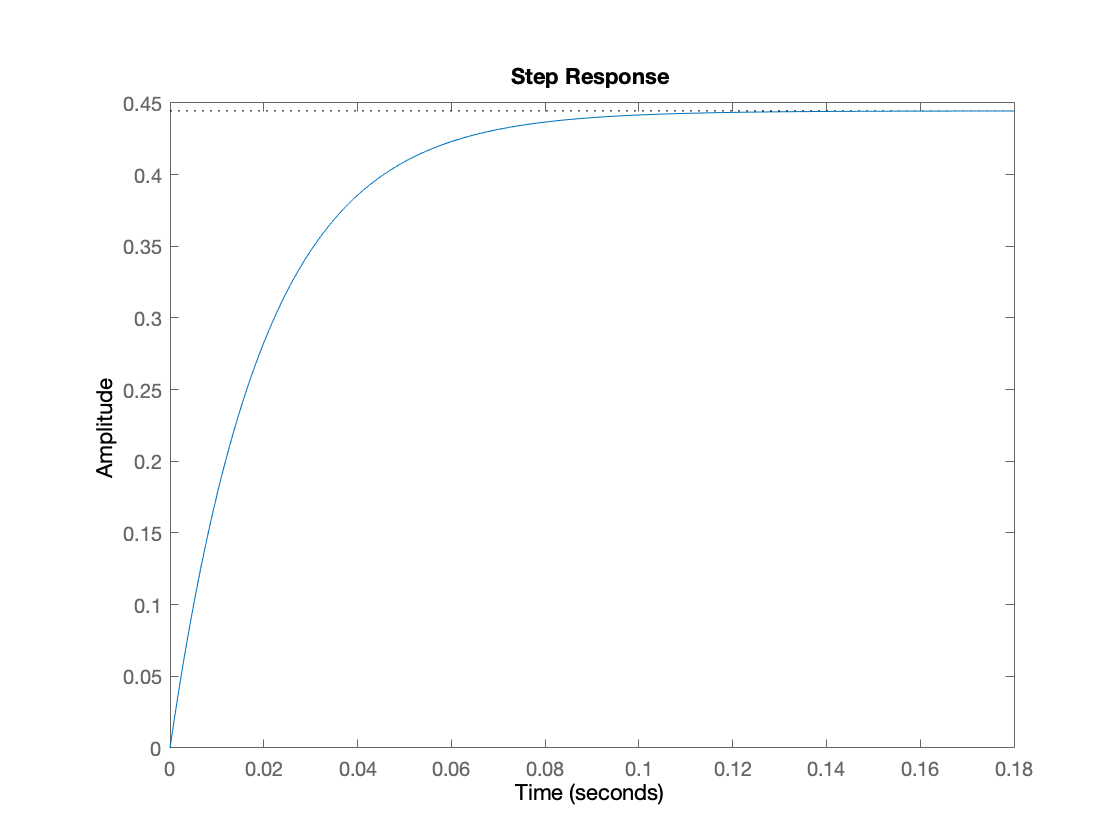


step(Gmf)

% Investigação de como o erro varia com Kp

for m = 1 : 10
    
    Kp = m;                 % variando o ganho do controlador
    Gc = Kp;                % controlador
    Gma = Gp*Gc;            % ganho de malha aberta

    Gmf = feedback(Gma,1);  % ganho de malha aberta com realimentação unitária
    
    polo(m) = roots(cell2mat(Gmf.Denominator))
    
    step(Gmf)
    
    if m == 1
        hold;
    end
    
end

polo =   -50.5614  -73.0346  -95.5077 -117.9809 -140.4540 -162.9272 -185.4003 -207.8735 -230.3466 -252.8198


Current plot held


polo =   -50.5614  -73.0346  -95.5077 -117.9809 -140.4540 -162.9272 -185.4003 -207.8735 -230.3466 -252.8198


polo =   -50.5614  -73.0346  -95.5077 -117.9809 -140.4540 -162.9272 -185.4003 -207.8735 -230.3466 -252.8198


polo =   -50.5614  -73.0346  -95.5077 -117.9809 -140.4540 -162.9272 -185.4003 -207.8735 -230.3466 -252.8198


polo =   -50.5614  -73.0346  -95.5077 -117.9809 -140.4540 -162.9272 -185.4003 -207.8735 -230.3466 -252.8198


polo =   -50.5614  -73.0346  -95.5077 -117.9809 -140.4540 -162.9272 -185.4003 -207.8735 -230.3466 -252.8198


polo =   -50.5614  -73.0346  -95.5077 -117.9809 -140.4540 -162.9272 -185.4003 -207.8735 -230.3466 -252.8198


polo =   -50.5614  -73.0346  -95.5077 -117.9809 -140.4540 -162.9272 -185.4003 -207.8735 -230.3466 -252.8198


polo =   -50.5614  -73.0346  -95.5077 -117.9809 -140.4540 -162.9272 -185.4003 -207.8735 -230.3466 -252.8198


polo =   -50.5614  -73.0346  -95.5077 -117.9809 -140.4540 -162.9272 -185.4003 -207.8735 -230.3466 -252.8198


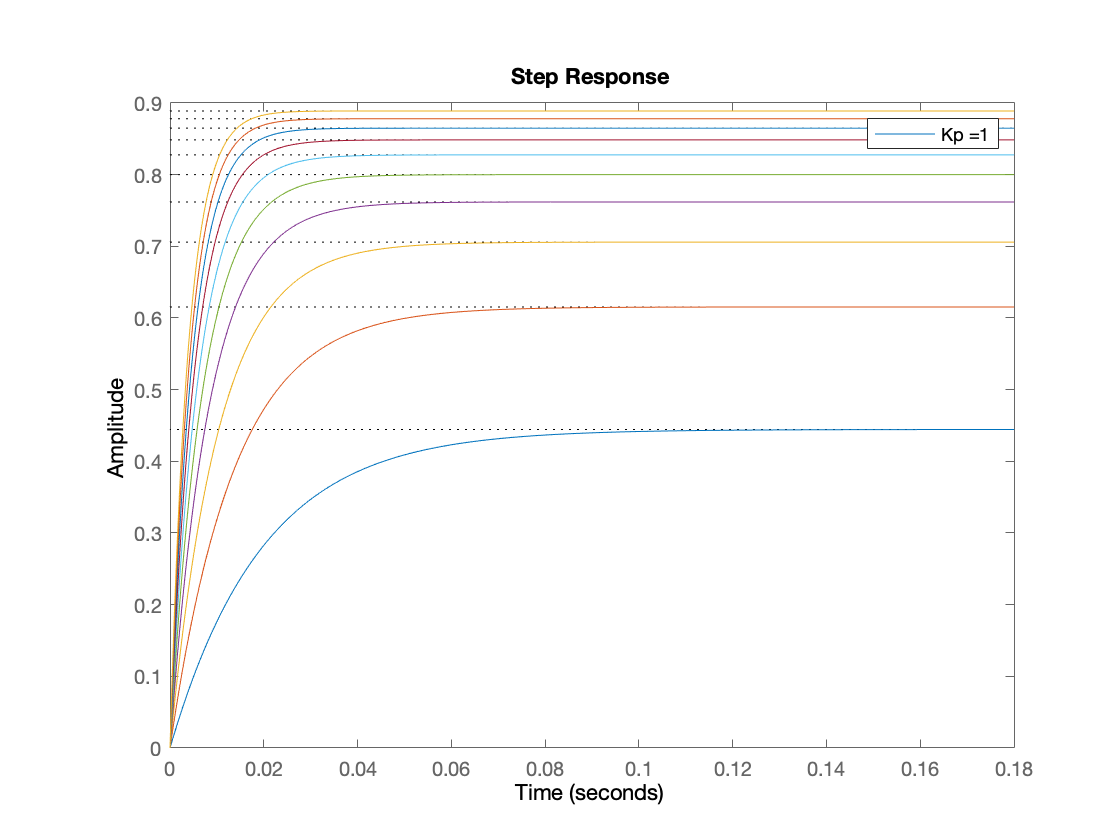


legend('Kp =1')

## Análise de lugar das raízes

## Análise de bode